% Train and test all data with one classifier

clear;
clc;

% ii=1;
% ii=7
F=[];
W=[];
for ii = 1:7
    number =int2str(ii);
    fname = ['Perturb_Data New/Chamber',number,'F.csv'];
    wname = ['Perturb_Data New/Chamber',number,'W.csv'];
    labels = categorical(["Fail","Working"]);
    F=[F; readmatrix(fname)];
    W=[W; readmatrix(wname)];
end

%Slice Data into chunks
chunkSize = 192; % Define the size of each chunk

numChunksF = ceil(size(F, 1) / chunkSize); % Calculate the number of chunks
numChunksW = ceil(size(W, 1) / chunkSize); % Calculate the number of chunks

chunksF = cell(numChunksF-1, 7); % Preallocate a cell array to hold the chunks
chunksW = cell(numChunksW-1, 7); % Preallocate a cell array to hold the chunks
offset = 90; % offset at the start

%fail case
for i = 1:numChunksF-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx =   min(offset+(i * chunkSize), size(F, 1));
    for j = 1:6
        chunksF{i,j} = F(startIdx:endIdx, j);
    end
    chunksF{i,7}=labels(1);
end

offset = 120; % offset at the start

%working case
for i = 1:numChunksW-1
    startIdx = offset+(i-1) * chunkSize + 1;
    endIdx = min(offset+(i * chunkSize), size(W, 1));
    for j = 1:6
        chunksW{i,j} = W(startIdx:endIdx, j);
    end
    chunksW{i,7}=labels(2);
end

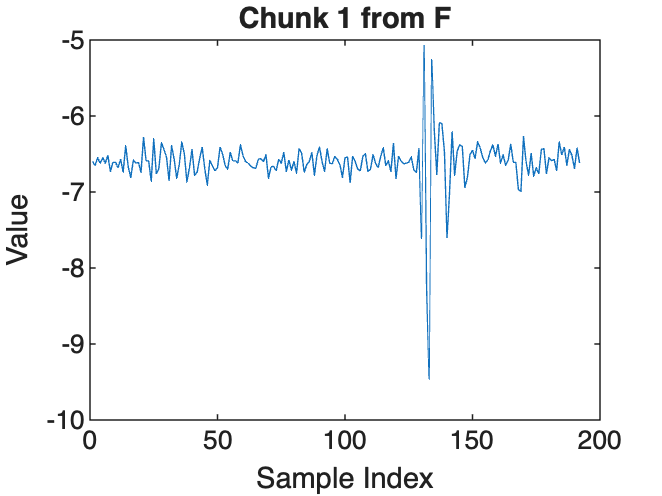

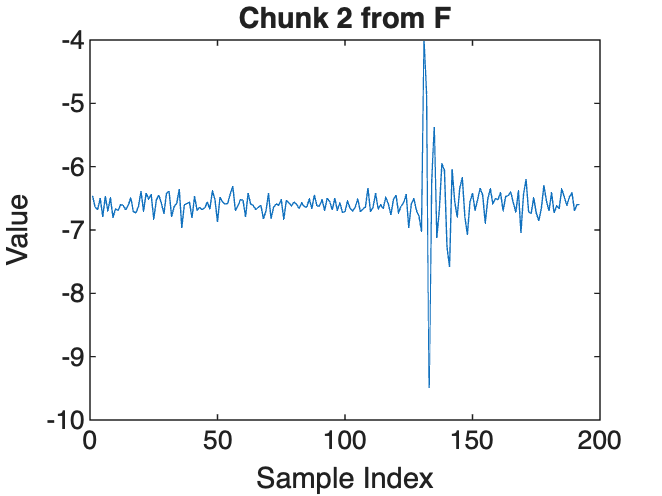

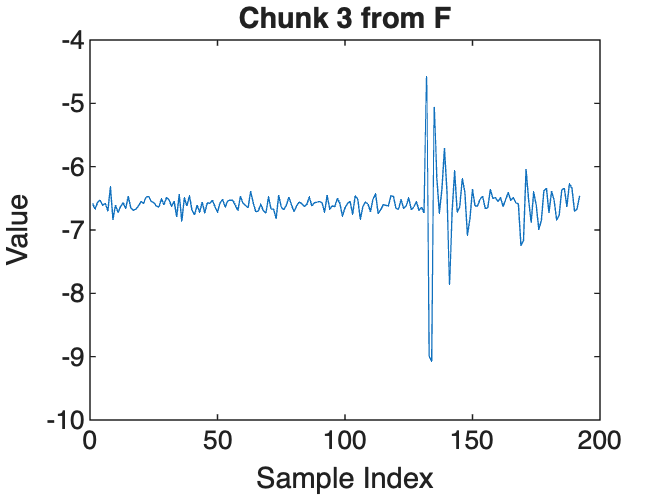

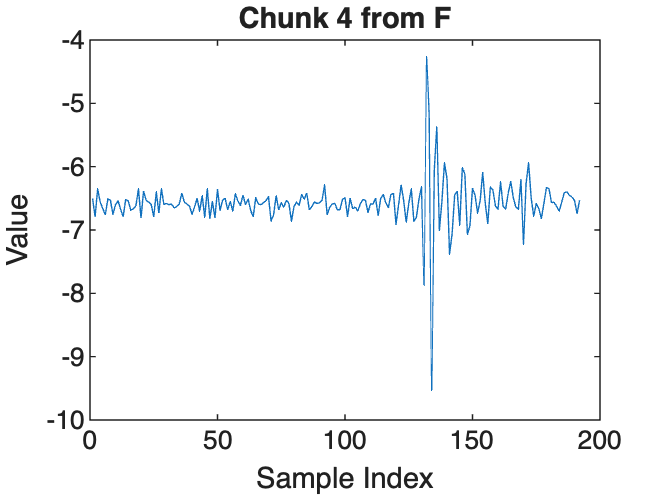

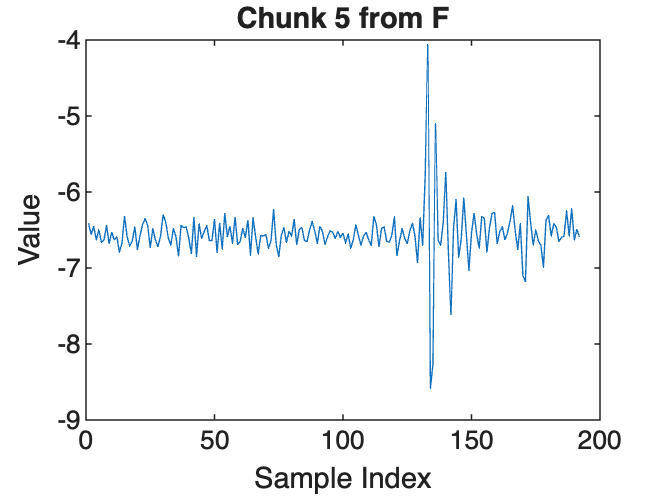

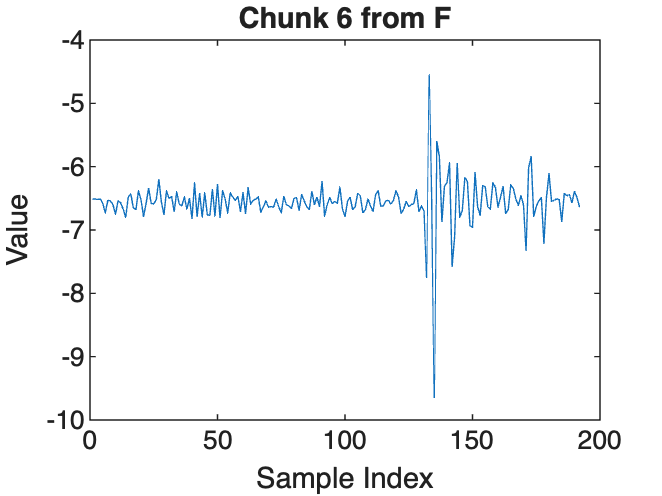

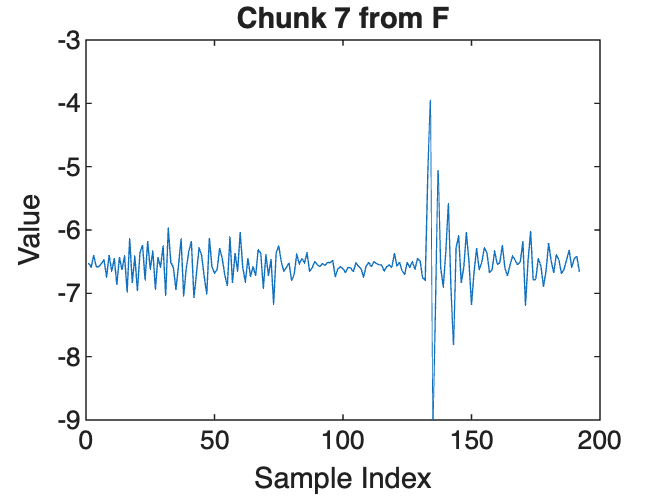

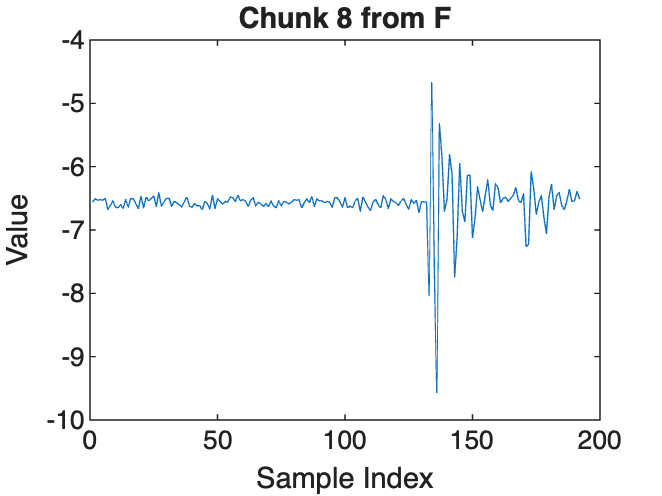

% Visualize 10 chunks from each cell fail
for i = 1:min(10, numChunksF)
    figure;
    plot(chunksF{i});
    title(['Chunk ', int2str(i), ' from F']);
    xlabel('Sample Index');
    ylabel('Value');
end

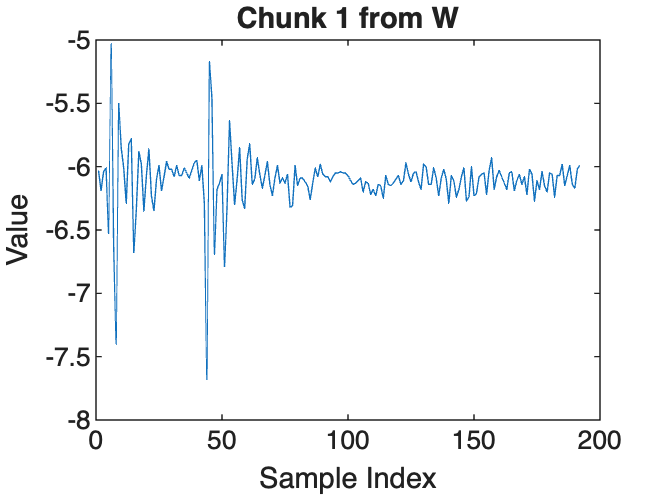

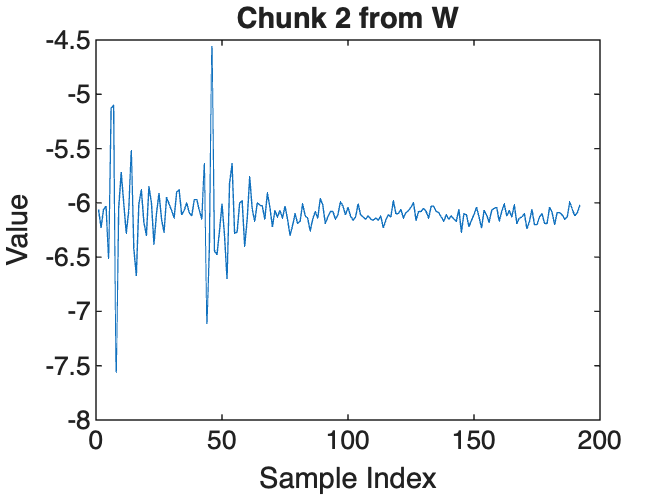

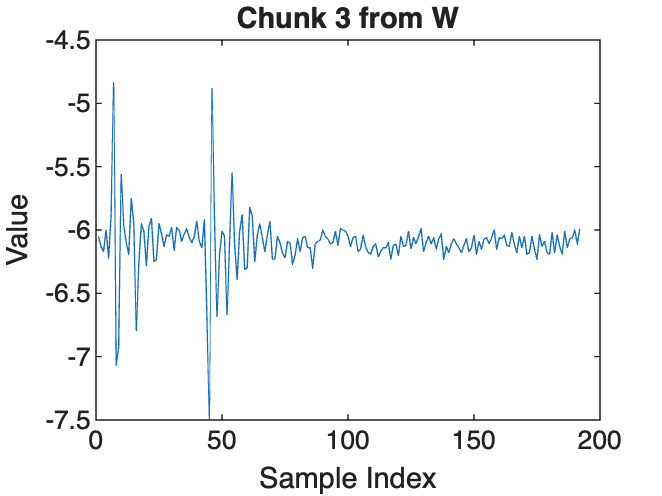

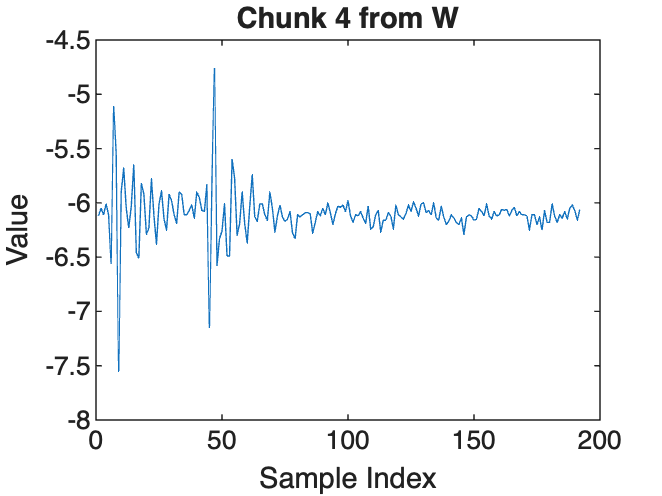

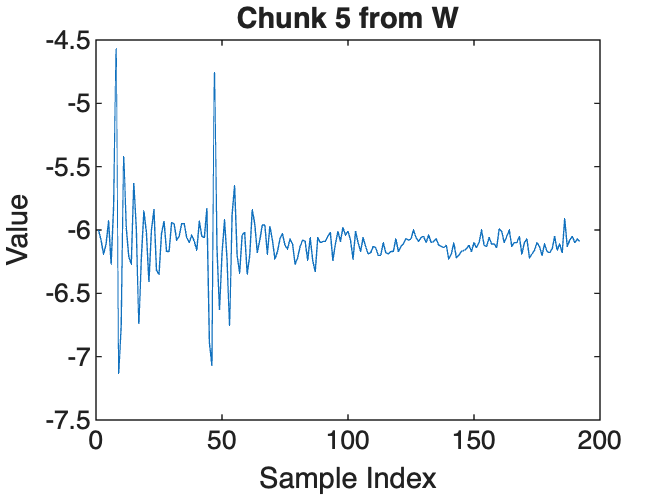

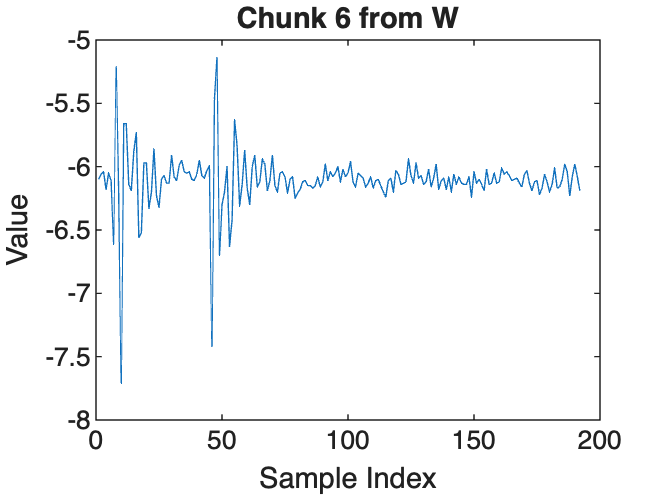

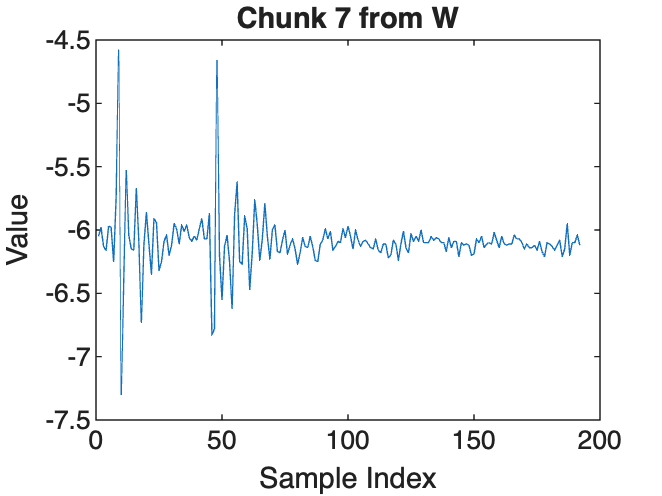

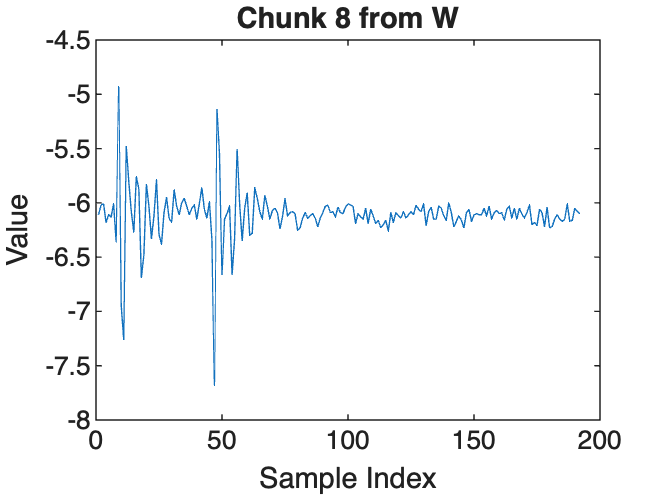


% Visualize 10 chunks from each cell working
for i = 1:min(10, numChunksW)
    figure;
    plot(chunksW{i+60});
    title(['Chunk ', int2str(i), ' from W']);
    xlabel('Sample Index');
    ylabel('Value');
end

% Create a table containing 7 columns (6 signals + 1 label)

WorkingData = chunksW;
FailData = chunksF;

trainData = cell(length(chunksW),2);
testData = cell(length(chunksF),2);

for i = 1: length(WorkingData)
    trainData{i,1} = [WorkingData{i,1},WorkingData{i,2},WorkingData{i,3},...
        WorkingData{i,4},WorkingData{i,5},WorkingData{i,6}];
    trainData{i,2}= labels(2);
end

for i = 1: length(FailData)
    testData{i} = [FailData{i,1},FailData{i,2},FailData{i,3},...
        FailData{i,4},FailData{i,5},FailData{i,6}];
    testData{i,2}=labels(1);
end




features = [trainData;testData]; %GenerateTop10Features(data);

%Create test-train split
rng("default")
idx = splitlabels(features(:,2), 0.9, 'randomized');
% 
fTrain  = features(idx{1},:);
fTest  = features (idx{2},:);

% featuresAfter = helperExtractLabeledData(featureTrain, ...
%    "Working");
col2 = fTrain(:,2);
col2cat = [col2{:}]';

workidx = col2cat == labels(2);

trainAfter =fTrain(workidx,1);

featureDimension = 10;

% define the LSTM net
detector = deepSignalAnomalyDetector(6,"lstmautoencoder", ...
    EncoderHiddenUnits=[16 32], ...
    DecoderHiddenUnits=16, ...
    WindowLength="fullSignal", ...
    ThresholdMethod="mean", ...
    ThresholdParameter=0.8);


% t2c = @(in)cellfun(@transpose, ...
%     mat2cell(in(:,2:end).Variables,ones(height(in),1)), ...
%     UniformOutput=false);
t2c = @(in) mat2cell(in(:,2:end-1).Variables,ones(height(in),1)), ...
    UniformOutput=false ;

t2c = function_handle with value:
    @(in)mat2cell(in(:,2:end-1).Variables,ones(height(in),1))



options = trainingOptions("adam", ...
   Plots="training-progress", ...
   Verbose=false, ...
   MiniBatchSize=500,...
   MaxEpochs=200);


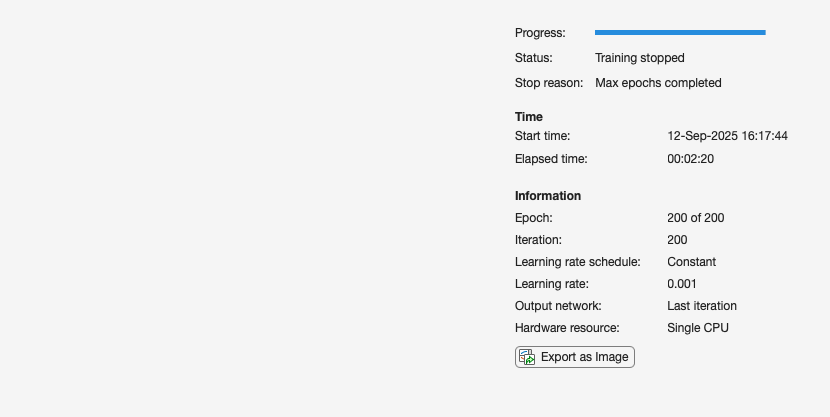

% trainDetector(detector,t2c(trainAfter),options)
trainDetector(detector,trainAfter,options)

col2 = fTest(:,2);
col2cat = [col2{:}]';

failidx = col2cat == labels(1);
testBefore = fTest(failidx,1);

aBefore = cell2mat(detect(detector,testBefore));
nBefore = sum(aBefore)/height(testBefore)*100

nBefore = 79.4521

col2 = fTest(:,2);
col2cat = [col2{:}]';

workidx = col2cat == labels(2);

testAfter = fTest(workidx,1);

aAfter = cell2mat(detect(detector,testAfter));
nAfter = sum(aAfter)/height(testAfter)*100

nAfter = 28.1690

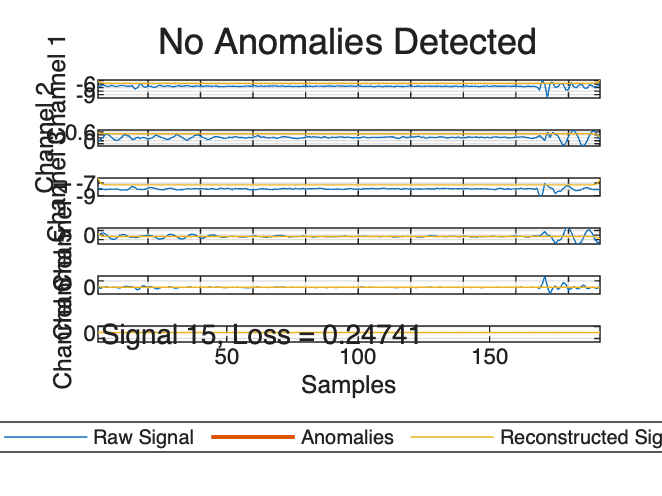

[~,lB] = detect(detector,testBefore);

ndN = find(~aBefore);
ndN = ndN(randi(length(ndN)));

plotAnomalies(detector,testBefore(ndN,:), ...
    PlotReconstruction=true)
text(2,-3,"Signal " + ndN + ", Loss = " + lB(ndN))
ylim([-16 11])
grid on

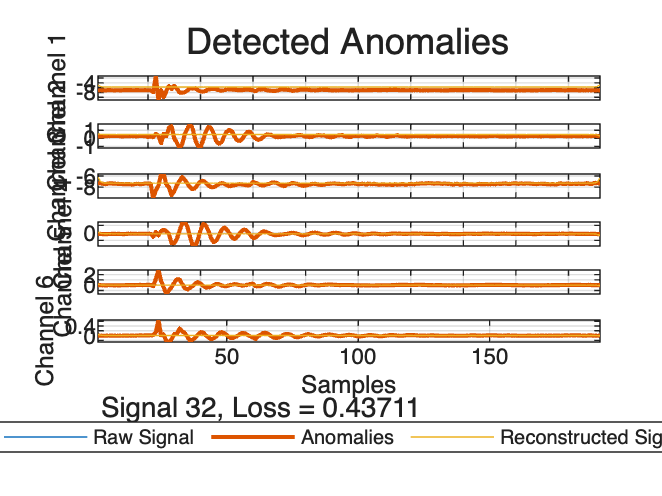

ndA = find(aBefore);
ndA = ndA(randi(length(ndA)));
plotAnomalies(detector,testBefore(ndA,:), ...
    PlotReconstruction=true)
text(2,-3,"Signal " + ndA + ", Loss = " + lB(ndA))
% ylim([-16 11])
grid on

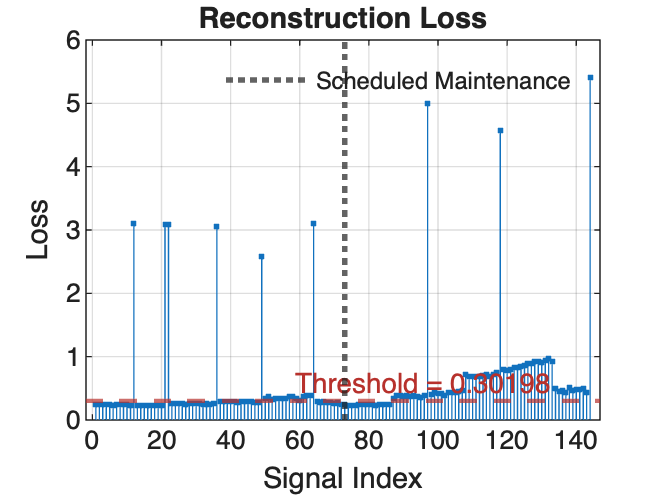

clf
q = plotLoss(detector,fTest(:,1));
xl = xline(height(testBefore),":",LineWidth=2, ...
    DisplayName="Scheduled Maintenance");
legend(xl,Box="off")

% ylim([0 15])

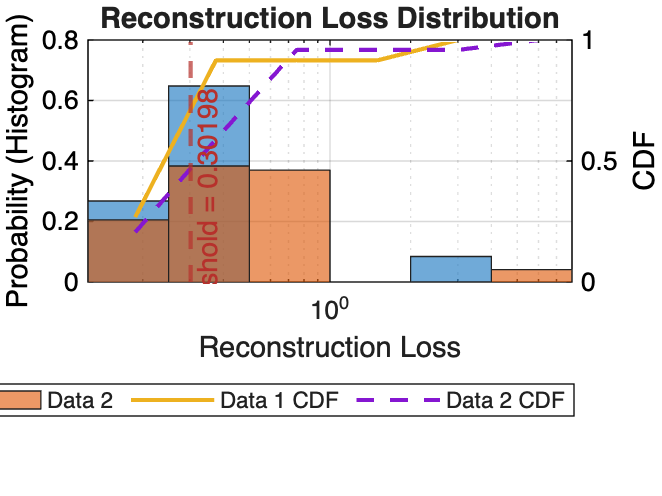

plotLossDistribution(detector,testAfter,testBefore);

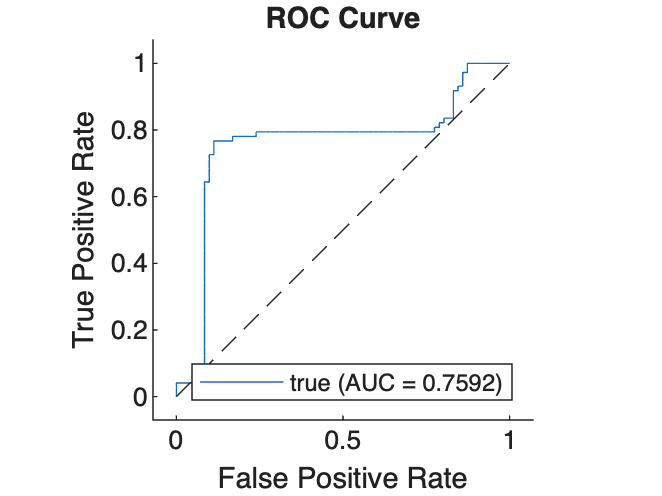

[~,lT] = detect(detector,fTest(:,1));
col2 = fTest(:,2);
col2cat = [col2{:}]';

failidx = col2cat == labels(1);

rocc = rocmetrics(failidx,cell2mat(lT),true);
plot(rocc,ShowModelOperatingPoint=false)